### Practice 0

### Missing data and synchronization

### Data from FRED

Creating time series and timetables

Synchronize and fill missing values

This version 12/09/2024

clear all
% Getting data from FRED
url = 'https://fred.stlouisfed.org/';
c = fred(url);
format bank
%3-Month Treasury Bill Secondary Market Rate, Discount Basis (DTB3)
% Daily data. Yields in percent per annum
% Format month/day/year
series = 'DTB3'; 
startdate = '04/01/1954'; % beginning of date range for historical data
enddate = '09/01/2024'; % ending of date range for historical data
d3m = fetch(c,series,startdate,enddate)

d3m = struct with fields:
                  NOTE: ' THIS DATA FILE WILL CHANGE! To improve accessibility of data for all users, we will convert this file from a text format to an html table by the end of June 2024.Title: 3-Month Treasury Bill Secondary Market Rate, Discount Basis'
              SeriesID: ' DTB3'
                Source: ' Board of Governors of the Federal Reserve System (US)'
               Release: ' H.15 Selected Interest Rates'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Daily'
                 Units: ' Percent'
             DateRange: ' 1954-01-04 to 2024-09-10'
           LastUpdated: ' 2024-09-11 3:17 PM CDT'
                 Notes: ' Discount Basis'
                  Data: [18372×2 double]


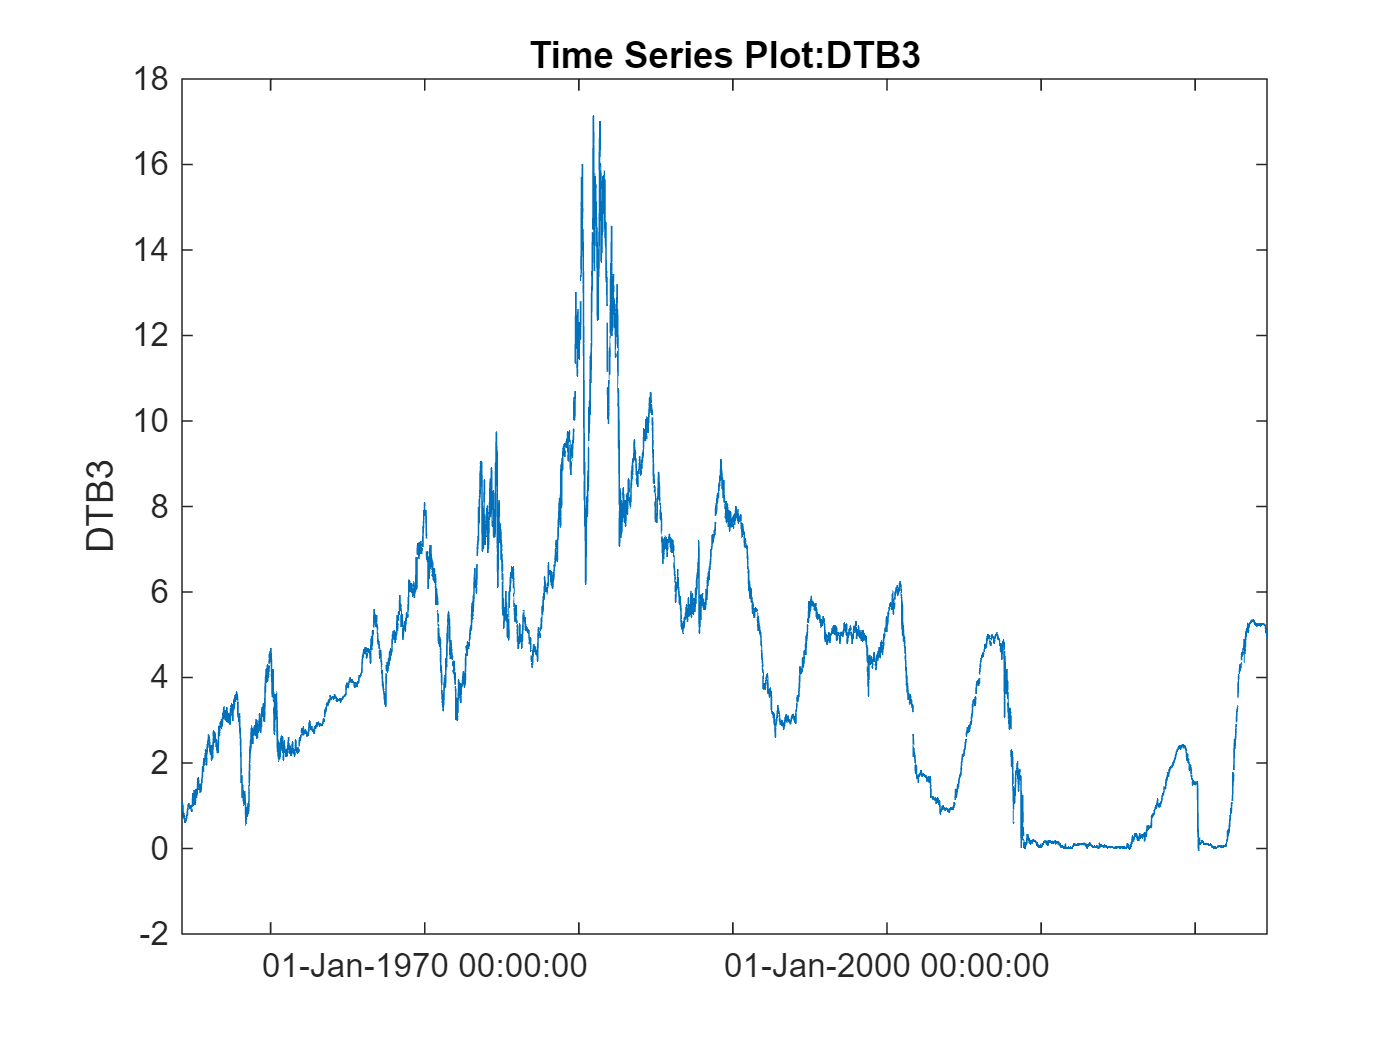

dts3m = timeseries([d3m.Data(:,2)], datestr(d3m.Data(:,1)));
dts3m.Name = series;
plot(dts3m);

% The series presents several missing data 

% 1-Year Treasury Bill Secondary Market Rate, Discount Basis (DTB1YR)
% Daily data. Yields in percent per annum
series = 'DTB1YR'; 
startdate = '07/15/1960'; % beginning of date range for historical data
enddate = '09/01/2023'; % ending of date range for historical data
d1Y = fetch(c,series,startdate,enddate)

d1Y = struct with fields:
                  NOTE: ' THIS DATA FILE WILL CHANGE! To improve accessibility of data for all users, we will convert this file from a text format to an html table by the end of June 2024.Title: 1-Year Treasury Bill Secondary Market Rate, Discount Basis'
              SeriesID: ' DTB1YR'
                Source: ' Board of Governors of the Federal Reserve System (US)'
               Release: ' H.15 Selected Interest Rates'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Daily'
                 Units: ' Percent'
             DateRange: ' 1959-07-15 to 2024-09-10'
           LastUpdated: ' 2024-09-11 3:17 PM CDT'
                 Notes: ' Discount Basis'
                  Data: [16471×2 double]


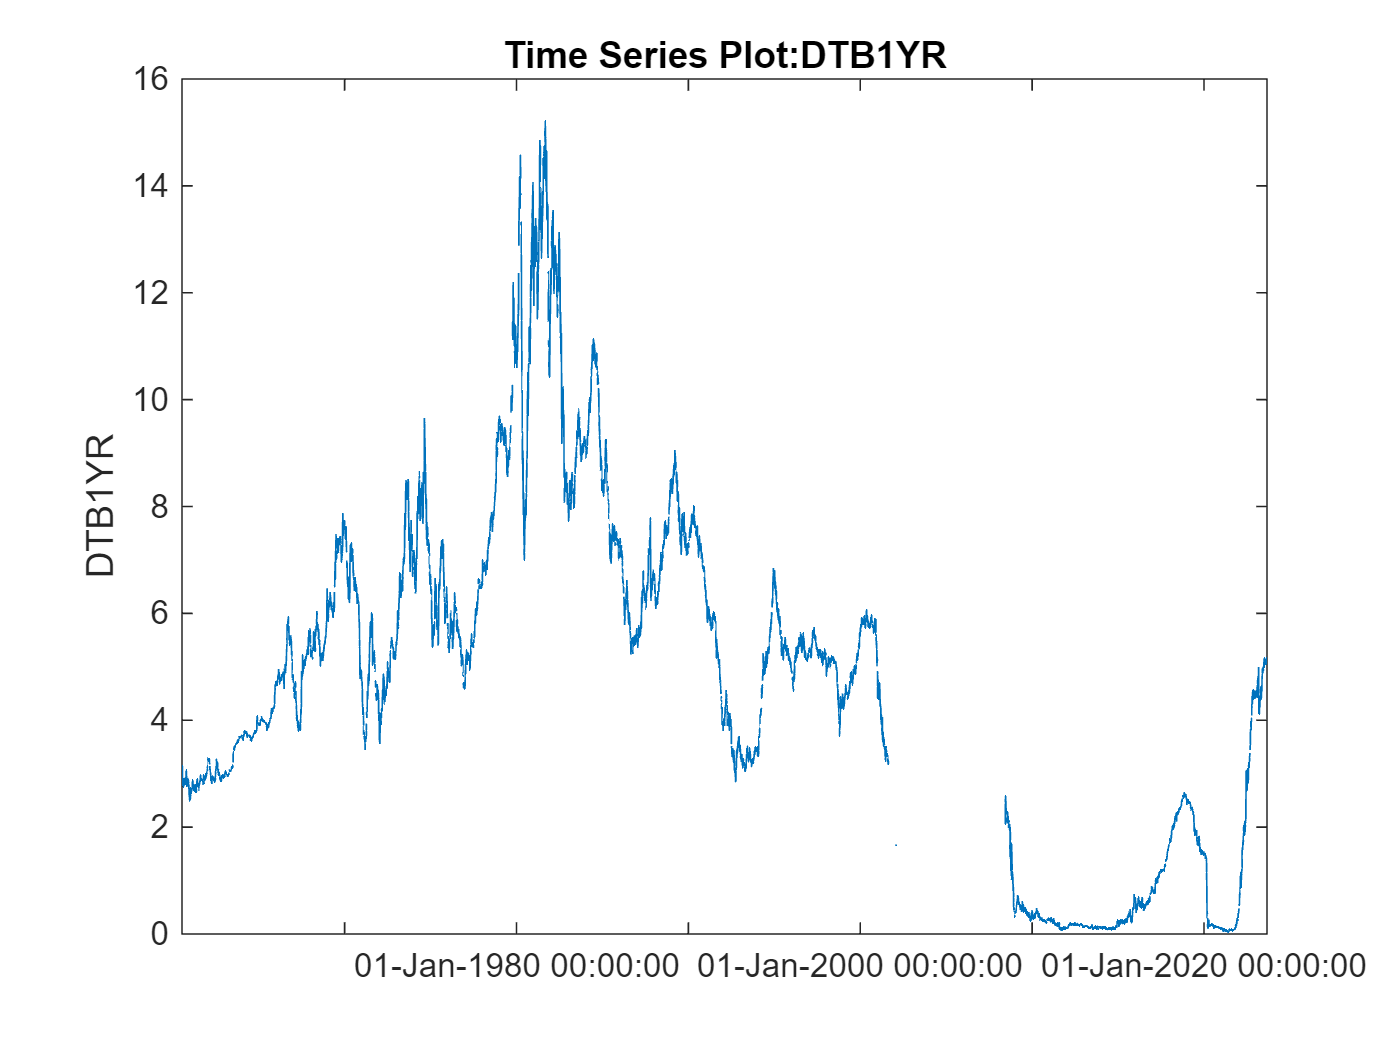

dts1y = timeseries([d1Y.Data(:,2)], datestr(d1Y.Data(:,1)));
dts1y.Name = series;
plot(dts1y);

% Create timetables

TT3m = timeseries2timetable(dts3m)

TT3m = 18372×1 timetable
       Time        DTB3
    ___________    ____

    01-Apr-1954    1.02
    02-Apr-1954    1.00
    05-Apr-1954    0.98
    06-Apr-1954    0.97
    07-Apr-1954    1.00
    08-Apr-1954    1.00
    09-Apr-1954    1.03
    12-Apr-1954    1.04
    13-Apr-1954    1.06
    14-Apr-1954    1.04
    15-Apr-1954    1.03
    16-Apr-1954    1.03
    19-Apr-1954    1.02
    20-Apr-1954    1.00
    21-Apr-1954    1.00
    22-Apr-1954    0.98


TT1y = timeseries2timetable(dts1y)

TT1y = 16471×1 timetable
       Time        DTB1YR
    ___________    ______

    15-Jul-1960     3.11 
    18-Jul-1960     3.09 
    19-Jul-1960     3.10 
    20-Jul-1960     3.12 
    21-Jul-1960     3.13 
    22-Jul-1960     3.14 
    25-Jul-1960     3.12 
    26-Jul-1960     2.95 
    27-Jul-1960     2.87 
    28-Jul-1960     2.86 
    29-Jul-1960     2.80 
    01-Aug-1960     2.78 
    02-Aug-1960     2.81 
    03-Aug-1960     2.84 
    04-Aug-1960     2.80 
    05-Aug-1960     2.80 


% Synchronize both series in a common sample

TTS=synchronize(TT3m,TT1y,'intersection')

TTS = 16471×2 timetable
       Time        DTB3    DTB1YR
    ___________    ____    ______

    15-Jul-1960    2.31     3.11 
    18-Jul-1960    2.26     3.09 
    19-Jul-1960    2.28     3.10 
    20-Jul-1960    2.34     3.12 
    21-Jul-1960    2.34     3.13 
    22-Jul-1960    2.35     3.14 
    25-Jul-1960    2.31     3.12 
    26-Jul-1960    2.23     2.95 
    27-Jul-1960    2.23     2.87 
    28-Jul-1960    2.23     2.86 
    29-Jul-1960    2.19     2.80 
    01-Aug-1960    2.10     2.78 
    02-Aug-1960    2.12     2.81 
    03-Aug-1960    2.17     2.84 
    04-Aug-1960    2.15     2.80 
    05-Aug-1960    2.13

% Fill missing data with optimal interpolation
% See other vailable methods is command "fillmissing"
TTS=fillmissing(TTS,'pchip')

TTS = 16471×2 timetable
       Time        DTB3    DTB1YR
    ___________    ____    ______

    15-Jul-1960    2.31     3.11 
    18-Jul-1960    2.26     3.09 
    19-Jul-1960    2.28     3.10 
    20-Jul-1960    2.34     3.12 
    21-Jul-1960    2.34     3.13 
    22-Jul-1960    2.35     3.14 
    25-Jul-1960    2.31     3.12 
    26-Jul-1960    2.23     2.95 
    27-Jul-1960    2.23     2.87 
    28-Jul-1960    2.23     2.86 
    29-Jul-1960    2.19     2.80 
    01-Aug-1960    2.10     2.78 
    02-Aug-1960    2.12     2.81 
    03-Aug-1960    2.17     2.84 
    04-Aug-1960    2.15     2.80 
    05-Aug-1960    2.13

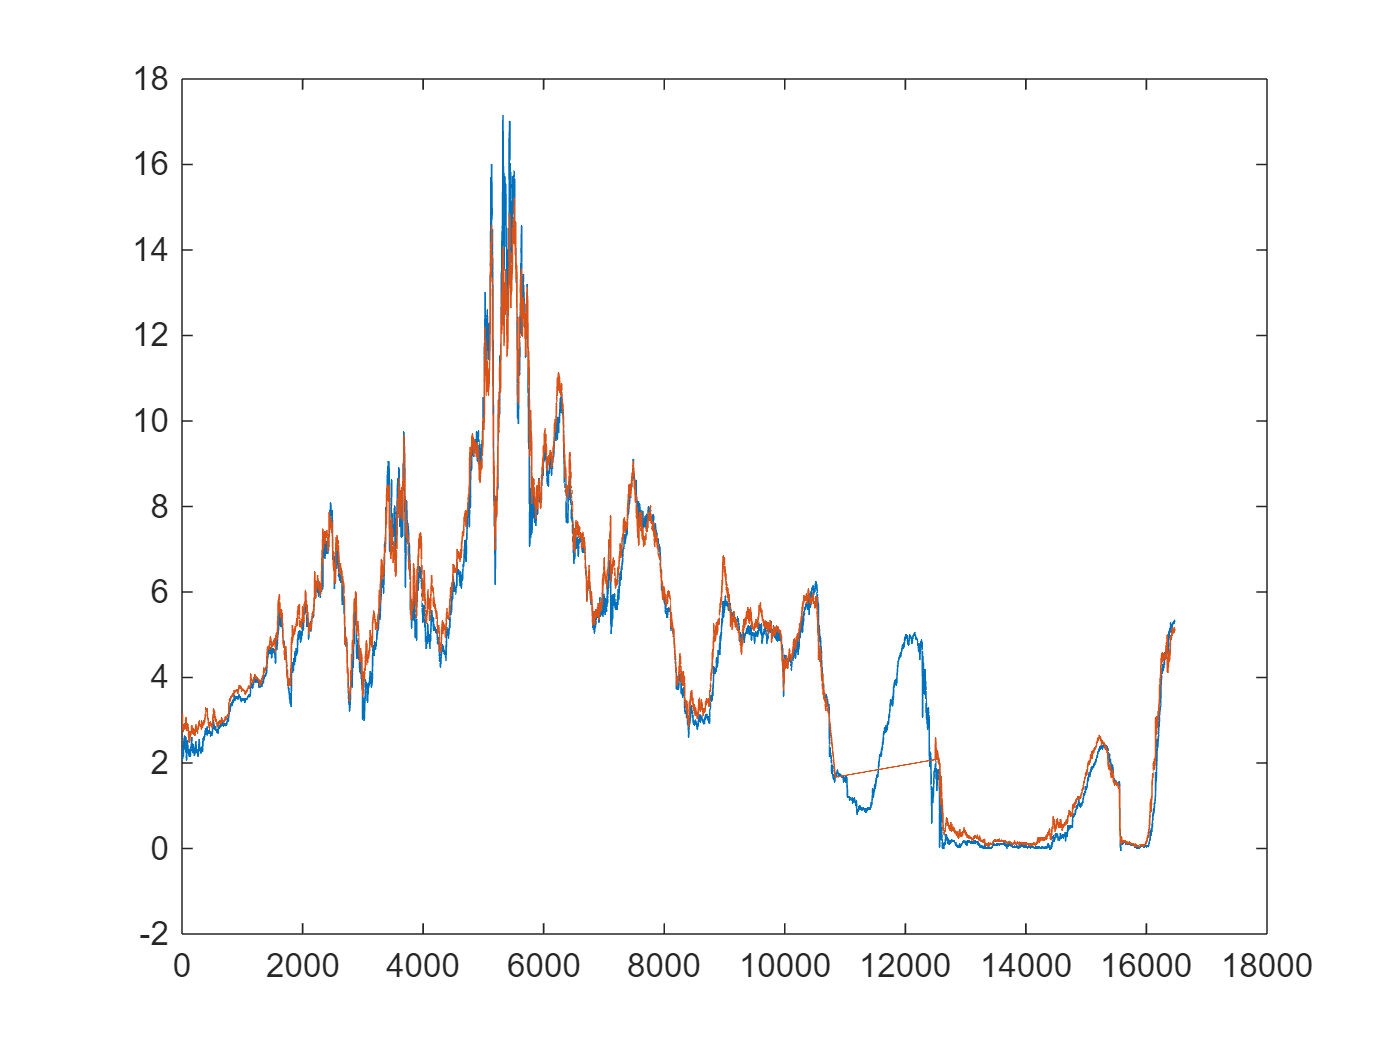

plot([TTS.DTB3 TTS.DTB1YR])

% Close FRED 

close(c)